clear;clc;

## Properties

## WATER PROPERTIES

water_temp = readtable("HX Properties.xlsx", 'Sheet', 1, 'Range', 'A5:A25'); water_temp = table2array(water_temp);
water_rho = readtable("HX Properties.xlsx", 'Sheet', 1, 'Range', 'B5:B25'); water_rho = table2array(water_rho);
water_cp = readtable("HX Properties.xlsx", 'Sheet', 1, 'Range', 'C5:C25'); water_cp = table2array(water_cp);
water_k = readtable("HX Properties.xlsx", 'Sheet', 1, 'Range', 'D5:D25'); water_k = table2array(water_k);
water_mu = readtable("HX Properties.xlsx", 'Sheet', 1, 'Range', 'E5:E25'); water_mu = table2array(water_mu);
water_Pr = readtable("HX Properties.xlsx", 'Sheet', 1, 'Range', 'F5:F25'); water_Pr = table2array(water_Pr);

% rho
f_rho = fit(water_temp, water_rho, 'poly3');
% plot(f_rho, water_temp, water_rho);
coeff_rho = coeffvalues(f_rho);
rho_water = @(temp) (coeff_rho(1)*temp.^3 + coeff_rho(2)*temp.^2 + coeff_rho(3)*temp + coeff_rho(4));

% cp
f_cp = fit(water_temp, water_cp, 'poly3');
% plot(f_cp, water_temp, water_cp);
coeff_cp = coeffvalues(f_cp);
cp_water = @(temp) (coeff_cp(1)*temp^3 + coeff_cp(2)*temp^2 + coeff_cp(3)*temp + coeff_cp(4));

% k
f_k = fit(water_temp, water_k, 'poly3');
% plot(f_k, water_temp, water_k);
coeff_k = coeffvalues(f_k);
k_water = @(temp) (coeff_k(1)*temp^3 + coeff_k(2)*temp^2 + coeff_k(3)*temp + coeff_k(4));

% mu
f_mu = fit(water_temp, water_mu, 'poly3');
% plot(f_mu, water_temp, water_mu);
coeff_mu = coeffvalues(f_mu);
mu_water = @(temp) (coeff_mu(1)*temp.^3 + coeff_mu(2)*temp.^2 + coeff_mu(3)*temp + coeff_mu(4));

% Pr
f_Pr = fit(water_temp, water_Pr, 'poly3');
% plot(f_Pr, water_temp, water_Pr);
coeff_Pr = coeffvalues(f_Pr);
Pr_water = @(temp) (coeff_Pr(1)*temp^3 + coeff_Pr(2)*temp^2 + coeff_Pr(3)*temp + coeff_Pr(4));


## ENGINE OIL PROPERTIES

oil_temp = readtable("HX Properties.xlsx", 'Sheet', 2, 'Range', 'A4:A12'); oil_temp = table2array(oil_temp);
oil_rho = readtable("HX Properties.xlsx", 'Sheet', 2, 'Range', 'B4:B12'); oil_rho = table2array(oil_rho);
oil_cp = readtable("HX Properties.xlsx", 'Sheet', 2, 'Range', 'C4:C12'); oil_cp = table2array(oil_cp);
oil_k = readtable("HX Properties.xlsx", 'Sheet', 2, 'Range', 'D4:D12'); oil_k = table2array(oil_k);
oil_mu = readtable("HX Properties.xlsx", 'Sheet', 2, 'Range', 'E4:E12'); oil_mu = table2array(oil_mu);
oil_Pr = readtable("HX Properties.xlsx", 'Sheet', 2, 'Range', 'F4:F12'); oil_Pr = table2array(oil_Pr);

% rho
f_rho = fit(oil_temp, oil_rho, 'poly3');
% plot(f_rho, oil_temp, oil_rho);
coeff_rho = coeffvalues(f_rho);
rho_oil = @(temp) (coeff_rho(1)*temp^3 + coeff_rho(2)*temp^2 + coeff_rho(3)*temp + coeff_rho(4));

% cp
f_cp = fit(oil_temp, oil_cp, 'poly3');
% plot(f_cp, oil_temp, oil_cp);
coeff_cp = coeffvalues(f_cp);
cp_oil = @(temp) (coeff_cp(1)*temp^3 + coeff_cp(2)*temp^2 + coeff_cp(3)*temp + coeff_cp(4));

% k
f_k = fit(oil_temp, oil_k, 'poly3');
% plot(f_k, oil_temp, oil_k);
coeff_k = coeffvalues(f_k);
k_oil = @(temp) (coeff_k(1)*temp^3 + coeff_k(2)*temp^2 + coeff_k(3)*temp + coeff_k(4));

% mu
f_mu = fit(oil_temp, oil_mu, 'exp2');
% clf
% plot(f_mu, oil_temp, oil_mu);
coeff_mu = coeffvalues(f_mu);
mu_oil = @(temp) (coeff_mu(1)*exp(coeff_mu(2)*temp) + coeff_mu(3)*exp(coeff_mu(4)*temp)) ;
% mu_oil(105)

% Pr
f_Pr = fit(oil_temp, oil_Pr, 'exp2');
% plot(f_Pr, oil_temp, oil_Pr);
coeff_Pr = coeffvalues(f_Pr);
Pr_oil = @(temp) (coeff_Pr(1)*exp(coeff_Pr(2)*temp) + coeff_Pr(3)*exp(coeff_Pr(4)*temp));


## Find NTU

mdot_cold = 3500;

Ti_cold = 15;
To_cold = 50;
delT_cold = To_cold - Ti_cold;

Ti_hot = 120;
delT_hot = 30;
To_hot = Ti_hot - delT_hot;

Tcold_bulk = (Ti_cold + To_cold)*0.5;
Thot_bulk = (Ti_hot + To_hot)*0.5;

cp_cold = cp_water(Tcold_bulk);
cp_hot = cp_oil(Thot_bulk);

qc = mdot_cold*cp_cold*delT_cold;

mdot_hot = qc/(cp_hot*delT_hot);

qh = mdot_hot*cp_hot*delT_hot;

q_actual = qc;

Ccold = mdot_cold*cp_cold; Cmin = Ccold; 
Chot = mdot_hot*cp_hot; Cmax = Chot;
c = Cmin/Cmax; 

q_max = Cmin*(Ti_hot - Ti_cold);

epsilon = q_actual/q_max;
NTU
NTU = (1/(c-1))*log((epsilon-1)/((epsilon*c) - 1))

NTU = 0.4830


UA_NTU = NTU*Cmin

UA_NTU = 7.0615e+06

## LMTD method

delT1 = Ti_hot - To_cold;
delT2 = To_hot - Ti_cold;

T_lm = (delT1 - delT2)/(log(delT1/delT2))

T_lm = 72.4713


UA_lm = qc/T_lm

UA_lm = 7.0615e+06

## Geometric properties, friction factor, Re, h

% Theoretical UA = 7.0615E6
% Change these five parameters to get the same UA as the theoretical one
Di = 0.0254*2 %inner tube diameter

Di = 0.0508

t = 0.00508 %thickness of inner tube

t = 0.0051

Do = 3 %outer tube diameter

Do = 3

L = 25.9 %length of tubes

L = 25.9000

n_max = floor(Do^2/(Di + (2*t))^2) %Max number of tubes that can fit in the shell = floor(Do^2/(Di + (2*t))^2)

n_max = 2421

n = 1800 %number of tubes         

n = 1800


k_copper = 397; %tubes are made up of copper

CSAi = pi*Di^2*.25 %cross sectional area of inner tube

CSAi = 0.0020

CSAo = 0.25*pi*Do^2 - (n*0.25*pi*(Di+(2*t))^2) %cross sectional area of outer tube

CSAo = 1.8150

SAi = n*pi*Di*L %surface area of inner tube

SAi = 7.4402e+03

SAo = n*pi*(Di+(2*t))*L %surface area of outer tube

SAo = 8.9283e+03


hydraulicDi = Di %hydraulic diameter of inner tube 

hydraulicDi = 0.0508

hydraulicDo = (pi*(Do^2 - (n*(Di+(2*t))^2)))/((pi*Do) + (n*pi*(Di+(2*t)))) %hydraulic diameter of outer tube

hydraulicDo = 0.0205


Vi = (mdot_cold/n)/(rho_water(Tcold_bulk)*CSAi) %velocity of inner tubes

Vi = 0.9643

Vo = (mdot_hot)/(rho_oil(Thot_bulk)*CSAo) %velocity of outer tube

Vo = 5.0081


Rei = (rho_water(Tcold_bulk)*Vi*hydraulicDi)/mu_water(Tcold_bulk) %Reynolds number of inner tubes

Rei = 6.5040e+04

Reo = (rho_oil(Thot_bulk)*Vo*hydraulicDo)/mu_oil(Thot_bulk) %Reynolds number of outer tube

Reo = 5.6530e+03


fi = (0.790*log(Rei) - 1.64)^-2 %friction factor of inner tube

fi = 0.0198

fo = (0.790*log(Reo) - 1.64)^-2 %friction factor of outer tube

fo = 0.0372


Nu_cold = ((fi/8)*(Rei-1000)*Pr_water(Tcold_bulk))/(1 + (12.7*sqrt(fi/8)*(Pr_water(Tcold_bulk)^(2/3) - 1))) %Nusselt number of inner tubes

Nu_cold = 358.2051

Nu_hot = ((fo/8)*(Reo-1000)*Pr_oil(Thot_bulk))/(1 + (12.7*sqrt(fo/8)*(Pr_oil(Thot_bulk)^(2/3) - 1))) %Nusselt number of outer tubes

Nu_hot = 130.5171


h_cold = (Nu_cold*k_water(Tcold_bulk))/hydraulicDi %heat transfer cofficient of inner tubes

h_cold = 4.3657e+03

h_hot = (Nu_hot*k_oil(Thot_bulk))/hydraulicDo %heat transfer coefficient of outer tubes

h_hot = 864.6153


UA = ((1/(h_hot*SAo)) + (log((Di + (2*t))/Di)/(n*2*pi*L*k_copper)) + (1/(h_cold*SAi)))^-1

UA = 6.1768e+06


% UA/1000

NTU = UA/Cmin

NTU = 0.4224

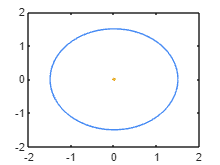


clf
drawcircle(0,0,Di)
hold on
drawcircle(0,0,Di+t)
drawcircle(0,0,Do)

## UA vs L

% % Theoretical UA = 7.0615E6
% % Change these five parameters to get the same UA as the theoretical one
% Di = 0.0254*2 %inner tube diameter
% t = 0.0127 %thickness of inner tube
% Do = 2.5 %outer tube diameter
% L = [8 10 11 12 13 14 15] %length of tubes
% n_max = floor(Do^2/(Di + (2*t))^2) %Max number of tubes that can fit in the shell = floor(Do^2/(Di + (2*t))^2)
% n = 800 %number of tubes         
% 
% k_copper = 398; %tubes are made up of copper
% 
% CSAi = pi*Di^2*.25 %cross sectional area of inner tube
% CSAo = 0.25*pi*Do^2 - (n*0.25*pi*(Di+(2*t))^2) %cross sectional area of outer tube
% SAi = n*pi*Di*L %surface area of inner tube
% SAo = n*pi*(Di+(2*t))*L %surface area of outer tube
% 
% hydraulicDi = Di %hydraulic diameter of inner tube 
% hydraulicDo = (pi*(Do^2 - (n*(Di+(2*t))^2)))/((pi*Do) + (n*pi*(Di+(2*t)))) %hydraulic diameter of outer tube
% 
% Vi = (mdot_cold/n)/(rho_water(Tcold_bulk)*CSAi) %velocity of inner tubes
% Vo = (mdot_hot)/(rho_oil(Thot_bulk)*CSAo) %velocity of outer tube
% 
% Rei = (rho_water(Tcold_bulk)*Vi*hydraulicDi)/mu_water(Tcold_bulk) %Reynolds number of inner tubes
% Reo = (rho_oil(Thot_bulk)*Vo*hydraulicDo)/mu_oil(Thot_bulk) %Reynolds number of outer tube
% 
% fi = (0.790*log(Rei) - 1.64)^-2 %friction factor of inner tube
% fo = (0.790*log(Reo) - 1.64)^-2 %friction factor of outer tube
% 
% Nu_cold = ((fi/8)*(Rei-1000)*Pr_water(Tcold_bulk))/(1 + (12.7*sqrt(fi/8)*(Pr_water(Tcold_bulk)^(2/3) - 1))) %Nusselt number of inner tubes
% Nu_hot = ((fo/8)*(Reo-1000)*Pr_oil(Thot_bulk))/(1 + (12.7*sqrt(fo/8)*(Pr_oil(Thot_bulk)^(2/3) - 1))) %Nusselt number of outer tubes
% 
% h_cold = (Nu_cold*k_water(Tcold_bulk))/hydraulicDi %heat transfer cofficient of inner tubes
% h_hot = (Nu_hot*k_oil(Thot_bulk))/hydraulicDo %heat transfer coefficient of outer tubes
% 
% UA = ((1./(n*h_hot.*SAo)) + (log(Do/Di)./(n*2*pi*L*k_copper)) + (1./(n*h_cold.*SAi))).^-1
% 
% plot(L, UA)


## UA vs number of tubes

% % Theoretical UA = 7.0615E6
% % Change these five parameters to get the same UA as the theoretical one
% Di = 0.0254*2 %inner tube diameter
% t = 0.0127 %thickness of inner tube
% Do = 2.5 %outer tube diameter
% L = 13.8 %length of tubes
% n_max = floor(Do^2/(Di + (2*t))^2) %Max number of tubes that can fit in the shell = floor(Do^2/(Di + (2*t))^2)
% n = [400 500 600 700 800 900] %number of tubes         
% 
% k_copper = 398; %tubes are made up of copper
% 
% CSAi = pi*Di^2*.25 %cross sectional area of inner tube
% CSAo = 0.25*pi*Do^2 - (n*0.25*pi*(Di+(2*t))^2) %cross sectional area of outer tube
% SAi = n*pi*Di*L %surface area of inner tube
% SAo = n*pi*(Di+(2*t))*L %surface area of outer tube
% 
% hydraulicDi = Di %hydraulic diameter of inner tube 
% hydraulicDo = (pi*(Do^2 - (n*(Di+(2*t))^2)))/((pi*Do) + (n*pi*(Di+(2*t)))) %hydraulic diameter of outer tube
% 
% Vi = (mdot_cold./n)./(rho_water(Tcold_bulk)*CSAi) %velocity of inner tubes
% Vo = (mdot_hot)./(rho_oil(Thot_bulk)*CSAo) %velocity of outer tube
% 
% Rei = (rho_water(Tcold_bulk)*Vi*hydraulicDi)/mu_water(Tcold_bulk) %Reynolds number of inner tubes
% Reo = (rho_oil(Thot_bulk)*Vo*hydraulicDo)/mu_oil(Thot_bulk) %Reynolds number of outer tube
% 
% fi = (0.790*log(Rei) - 1.64).^-2 %friction factor of inner tube
% fo = (0.790*log(Reo) - 1.64).^-2 %friction factor of outer tube
% 
% Nu_cold = ((fi./8).*(Rei-1000).*Pr_water(Tcold_bulk))./(1 + (12.7*sqrt(fi./8).*(Pr_water(Tcold_bulk)^(2/3) - 1))) %Nusselt number of inner tubes
% Nu_hot = ((fo./8).*(Reo-1000).*Pr_oil(Thot_bulk))./(1 + (12.7*sqrt(fo./8).*(Pr_oil(Thot_bulk)^(2/3) - 1))) %Nusselt number of outer tubes
% 
% h_cold = (Nu_cold*k_water(Tcold_bulk))/hydraulicDi %heat transfer cofficient of inner tubes
% h_hot = (Nu_hot*k_oil(Thot_bulk))/hydraulicDo %heat transfer coefficient of outer tubes
% 
% UA = ((1./(n.*h_hot.*SAo)) + (log(Do/Di)./(n*2*pi*L*k_copper)) + (1./(n.*h_cold.*SAi))).^-1
% 
% plot(n, UA)

## Pressure drop

temperature = linspace(15, 50, 100)';

hDi = Di; %hydraulic diameter of inner tube 

veli = (mdot_cold/n)./(rho_water(temperature)*CSAi); %velocity of inner tubes
velavg = mean(veli)

velavg = 0.9648

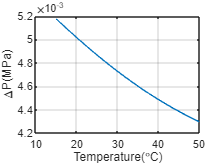

Reyi = (rho_water(temperature).*velavg.*hDi)./mu_water(temperature); %Reynolds number of inner tubes

frici = (0.790.*log(Reyi) - 1.64).^-2; %friction factor of inner tube

delP = (frici.*(L/Di).*(rho_water(temperature).*(velavg^2))*0.5);

clf
plot(temperature, delP/10^6)
xlabel("Temperature(\circC)")
ylabel('\DeltaP(MPa)')
grid on   